***KEMALETTİN KARA 1806A004 - HW1 ***

***QUESTİON 1***

reading = [4.617,4.436,5.039,6.053,4.642,4.859,5.583,5.606,5.242,5.513,5.435,4.809,5.214,4.850,4.550,5.317,5.033,4.906,5.145,5.493,5.196,5.097,5.139,5.025,4.612];
total =0 ;
devTotal = 0 ;
deviations=[];

%%%%%%%%%%%%%%%%%%%%% mean calculation  %%%%%%%%%%%%%%%%%%%%
for n = reading
    total = n + total;
end
averageMean = total / size(reading,2);

%%%%%%%%%%%%%%%%%%% deviation calculation  %%%%%%%%%%%%%%%%%
% dn = xn - xmean
for d = reading
    deviations = [deviations (d-averageMean)];
end
for n = deviations
    devTotal = abs(n) + devTotal;   
    
end
deviationMean = devTotal / size(reading,2);

%%%%%%%%% Standard deviation calculation and variance  %%%%%
std = sqrt(sum(deviations.^2)/(size(reading,2)-1));
var = std^2;


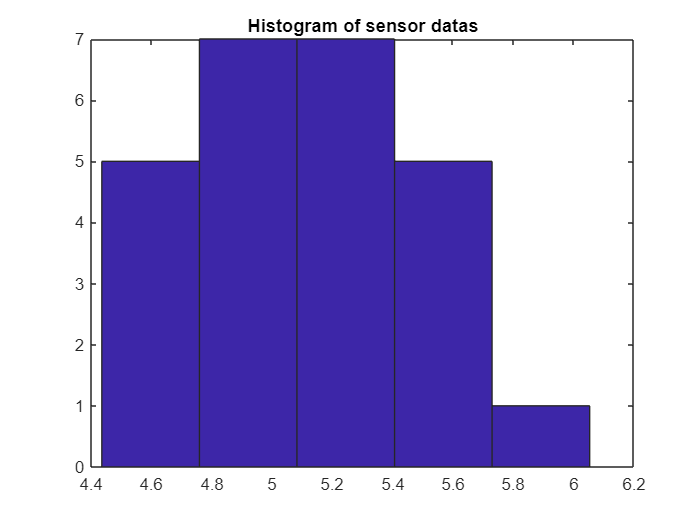

%%%%%%%%%%%%%%%%%%% PLotting Histogram  %%%%%%%%%%%%%%%%%%%%
 figure;
 hist(reading,5)
 title("Histogram of sensor datas")

***QUESTION 1 - PART F***

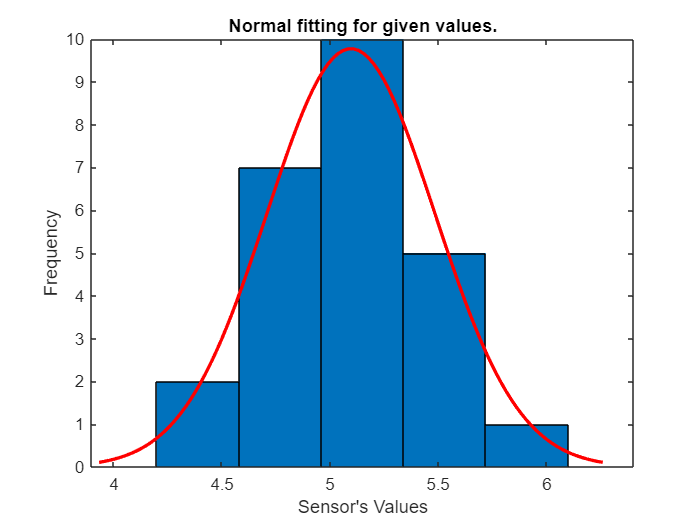

% Normal distribution has two parameter and these parameters are declared
% in above mean and standard deviation.

% Normal distribution fitting
figure;
histfit(reading)

ylabel("Frequency")
xlabel("Sensor's Values")
title("Normal fitting for given values.")

***QUESTION 1 - PART G ***

%%%%%%%%%%%%%%%%%%% Writing all results  %%%%%%%%%%%%%%%%%
fprintf("Summing of all element in the reading: %f\n",total)

Summing of all element in the reading: 127.411000


fprintf("Sum of deviations: %f\n",devTotal)

Sum of deviations: 7.558560


fprintf("Average mean: %f\n",averageMean)

Average mean: 5.096440


fprintf("Deviation mean: %f\n",deviationMean)

Deviation mean: 0.302342


fprintf("Standard deviation: %f\n",std)

Standard deviation: 0.387772


fprintf("Variance: %f\n",var)

Variance: 0.150367


***QUESTION 2 ***

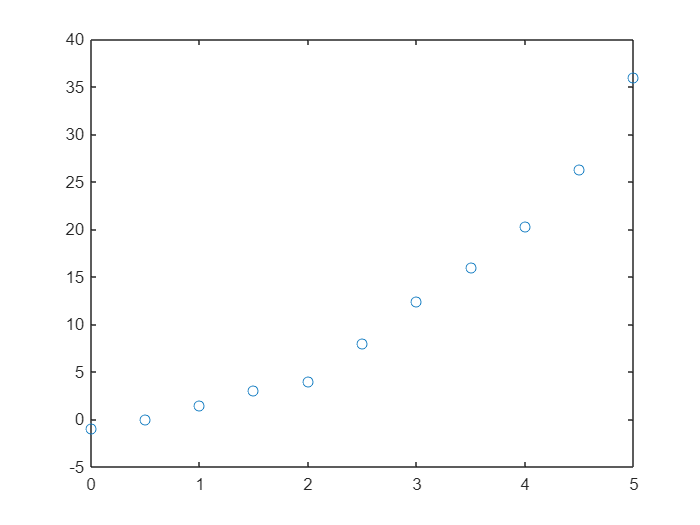

%%%%%%%%%%%%%%%%%%%%%%% Question 2  %%%%%%%%%%%%%%%%%%%%%%%%
X = [0.0, 0.5, 1.0, 1.5, 2.0, 2.5, 3.0, 3.5, 4.0, 4.5, 5.0];        %volt
Y = [-1.0, -0.0, 1.5, 3.0, 4.0, 8.0, 12.4, 16.0, 20.3, 26.3, 36.0]; % Newton
figure;
plot(X,Y,"o")

## **A) LİNEAR FİT**

func1 = polyfit(X,Y,1)

func1 =     6.9273   -5.8182


c = func1'  %transpoze

c =     6.9273
   -5.8182


poly1 = vpa(poly2sym(func1),3);
X1=X

X1 =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000


Y1=polyval(func1,X1)

Y1 =    -5.8182   -2.3545    1.1091    4.5727    8.0364   11.5000   14.9636   18.4273   21.8909   25.3545   28.8182


## **b) 2nd Order Polynomial Fit**

func2=polyfit(X,Y,2)

func2 =     1.4890   -0.5179   -0.2343


c=func2'    %transpoze

c =     1.4890
   -0.5179
   -0.2343


poly2=vpa(poly2sym(func2),3)

$$poly2 = 1.49\,x^{2}-0.518\,x-0.234$$

X2=X

X2 =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000


Y2=polyval(func2,X2)

Y2 =    -0.2343   -0.1210    0.7368    2.3392    4.6860    7.7774   11.6133   16.1937   21.5186   27.5881   34.4021


## **c) 3rd Order Polynomial Fit**

func3=polyfit(X,Y,3)

func3 =     0.1896    0.0671    2.1932   -1.0874


c=func3' %transpoze

c =     0.1896
    0.0671
    2.1932
   -1.0874


poly3=vpa(poly2sym(func3),3)

$$poly3 = 0.19\,x^{3}+0.0671\,x^{2}+2.19\,x-1.09$$

X3=X

X3 =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000


Y3=polyval(func3,X3)

Y3 =    -1.0874    0.0497    1.3625    2.9932    5.0841    7.7774   11.2152   15.5396   20.8930   27.4175   35.2552


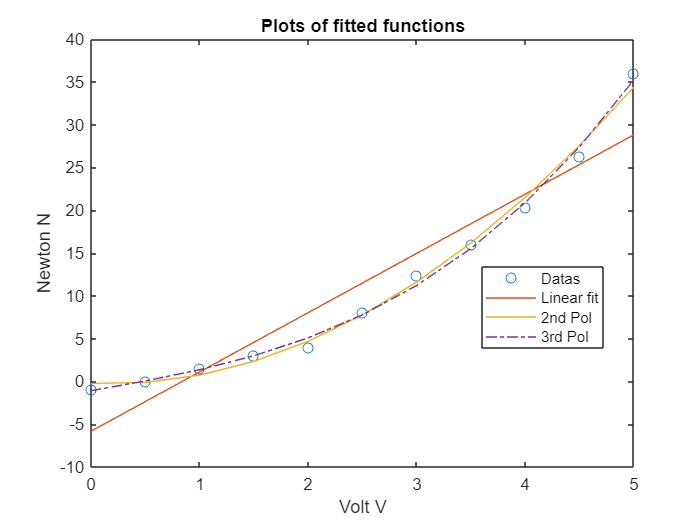

plot(X,Y,'o',X1,Y1,'-',X2,Y2,'-',X3,Y3,'-.')
title("Plots of fitted functions")
xlabel("Volt V")
ylabel("Newton N")
legend('Datas','Linear fit','2nd Pol','3rd Pol','Location', 'Best')

func1

func1 =     6.9273   -5.8182


func2

func2 =     1.4890   -0.5179   -0.2343


func3

func3 =     0.1896    0.0671    2.1932   -1.0874


%KEMALETTİN KARA HOMEWORK1 END

**Comparison and Comment**

When I compared it with hand calculations, I noticed that there were errors due to rounding errors. In general, I think that hand calculations will be a hundred percent match when these errors are ignored.That's all I can see, thank you sir.